Datos y normalización

clear
%sort data, asignar colonización por aridez (A) y normalización (función
%addData)
A=0.3;
load rawData.mat
data=zeros(size(rawData,1),size(rawData,2));
[data(:,1),I]=sort(rawData(:,1));
data(:,2:end)=rawData(I,2:end);
data(:,2:3)=data(:,2:3)./data(:,3);
%build final data array
data(:,2)=data(:,2).*(1-A.^data(:,4));

%cortar a 2 especies para pruebas
%data(any(data(:,1)>3,2),:)=[];
save data data;

Análisis

%definición del sistema de ecuaciones para encontrar puntos críticos
y=sym ("y" + [1:size(data,1)]);
eq=[data(1,2).*y(1).*(1-y(1))-y(1);data(2,2).*y(2).*(1-y(1)-y(2))-y(2)-data(1,2).*y(1).*y(2)];

%se resuelve el sistema y se pasa de strct a array (seguramente acepte
%mejoras)
s=solve(eq,y);
solSize=size(s.("y"+size(data,1)),1);
a=zeros(solSize,size(data,1));
for i=1:size(data,1)
    a(:,i)=s.("y"+i);
end

%jacobiano con "y" simbólico

J=jacobian(eq,y);

%sustituimos "y" por cada solución. Jev es un vector de matrices, val son
%sus valores propios

Jev=zeros(size(J,1),size(J,2),solSize);
val=zeros(solSize,size(data,1));

%se rellenan Jev y val
for i=1:solSize
Jev(:,:,i)=subs(J,y,a(i,:));
val(i,:)=eig(Jev(:,:,i));
end

%las soluciones estables son aquellas en las que todos los valores propios
%son menores que 0. Se utiliza val como índice para identificar las
%soluciones estables en "a"
stab=a(all(val<0,2),:);
stabSize=size(stab,1);
stabTable=array2table(stab,"RowNames","stability point "+[1:stabSize],"VariableNames","species "+[1:size(data,1)])


Integración

%no se puede poner @[t,y] eq porque y(n) ya está identificado con yn
%ode1=@(t,y) [data(1,2).*y(1).*(1-y(1))-y(1);data(2,2).*y(2).*(1-y(1)-y(2))-y(2)-data(1,2).*y(1).*y(2)];
          %  [data(1,2).*y(1).*(1-y(1))-y(1);data(2,2).*y(2).*(1-y(1)-y(2))-y(2)-data(1,2).*y(1).*y(2)]

          
y0=0.0001+zeros(size(data(:,2)));

%el próximo paso es buscar la forma de hacer el rango dinámico (hacerlo
%periódico es sencillo)
[t,y]=ode45(@ode1,[0,100],y0);

Representación

p=plot(t,y)

p =   6×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line


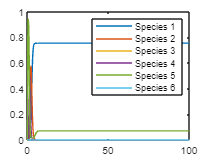

legend("Species " + data(1:end,1))

Pruebas